# Create tSNE plots of spike words from premotor window

## Load Sam's Adult Data and save as samCases

### Sam's adult data

% Load single unit cases (load only subset)
cd J:\Sam_adultRA\
% files = "case_ids_1_50"; % SU only, "case_ids_all_1_50" for %SUs + MUs
files = "case_ids_1_50"

files = "case_ids_1_50"

load("case_ids.mat",files);
samCaseNames = case_ids_1_50;

% Create Spike Words with time bin duration, dt
dt = 5; % in msec


Extract Spiketimes and Create Spike Words

casenames= samCaseNames;
allCases = struct();

for i = 1:length(casenames) % loop through each case

    % Load Case Params
    neuralcase = struct();
    casefilename = strcat(casenames{i},'.mat'); 
    load(casefilename,'case_id','birdname','syllablename','number_of_trials','c_entropy','acoustic_data');
    neuronname = 'day140';
    neuralcase.case_ID = case_id;
    neuralcase.birdname = birdname;
    neuralcase.syllablename = syllablename;
    neuralcase.neuronname = neuronname;
    neuralcase.n_trials = number_of_trials; 
    neuralcase.age = 140;
       
    % Save spike trains from motor window
    neuralcase.spiketrains = c_entropy; % t_assay = 0 millisec
    motorwin_data = c_entropy;

     % Calculate spike counts -already assumes 40 ms premotor window
    neuralcase.spikecounts = cellfun(@length, c_entropy);

    % Create Spike Words at a given dt
    pre_time = 0; post_time = 40; 
    binEdges = pre_time:dt:post_time; 
    struct_subname = ['dt' num2str(dt)];
    spikeWords = cellfun(@(x) histcounts(x, binEdges), motorwin_data, 'UniformOutput', false)';
    sylSpikeWords = cell2mat(spikeWords');
    neuralcase.spikeWords.(struct_subname) = sylSpikeWords;
    
        % Add to the data struct
    if ~isfield(allCases, birdname)
        allCases.(birdname) = struct();
    end

    % Use neuronname as the field name for storing data
    allCases.(birdname).(neuronname).(syllablename) = neuralcase;
end

samCases = allCases;

## Load Leila's data and save as leilaCases

%cd('C:\Users\LPASCU2\OneDrive - Emory University\SongbirdProject\Data\2025_Jan27')
cd('/Users/avusiri/Downloads/2025_Jan27')

% Load all .mat files in the current directory
files = dir('*.mat');
% allCases = struct();

% MANUALLY Define the motor window boundaries
% NOTE: PREMOTOR WINDOW IS ACTUALLY BOUNDED BY THE T_ASSAY - 40 MSEC
% Note: change so that times are aligned to syllable onset, not t_assay
premotor_duration = 0.04;
pre_time = -0.02; 
post_time = 0.04; 


% Create Spike Words with time bin duration, dt
dt = 0.005; % sec


Extract premotor window & create spike words 

% Load the data and calculate spike counts
neuronname = [];
prevNeuron = []; 
for i = 1:length(files)
    filename = files(i).name;
    neuralcase = load(filename, 'neuralcase').neuralcase; 
    
    % Extract relevant information
    prevNeuron = neuronname; 
    birdname = neuralcase.birdname;
    neuronname = neuralcase.neuronname;
    syllablename = neuralcase.syllablename;
    
    % Extract and save age from neuronname (first two digits, except for day153)
    if ~contains(neuronname, 'day153')
        neuralcase.age = str2double(neuronname(4:5)); 
    else
        neuralcase.age = 153;
    end

    % Extract Premotor Window - using t_assay as the onset of behavior
    % (t_assay is the time after syllable onset that the behavior is quantified)
    spikes = neuralcase.spiketrains; 
    syl_ons = neuralcase.syl_ons;
        % Convert spike times to be relative to syllable onset time
        relative_spikes = cellfun(@(x, y) x - y, spikes, ...
            num2cell(syl_ons), 'UniformOutput', false);
    
        % Filter spike times within the motor window
        % if isfield(neuralcase,'t_assay')
        %     pre_time = neuralcase.t_assay(1) - premotor_duration;
        %     post_time = neuralcase.t_assay(1);
        % else
        %     pre_time = 0 - premotor_duration;
        %     post_time = 0;
        % end

        motorwin_data = cellfun(@(x) x(x > pre_time & x < post_time), ...
            relative_spikes, 'UniformOutput', false);
        
    % Calculate spike counts in premotor window
    neuralcase.spikecounts = cellfun(@length, motorwin_data);

    % Create Spike Words at a given dt
    binEdges = pre_time:dt:post_time; 
    struct_subname = ['dt' num2str(dt*1000)];
    spikeWords = cellfun(@(x) histcounts(x, binEdges), motorwin_data, 'UniformOutput', false)';
    sylSpikeWords = cell2mat(spikeWords');
    neuralcase.spikeWords.(struct_subname) = sylSpikeWords;

    % Use neuronname as the field name for storing data
    allCases.(birdname).(neuronname).(syllablename) = neuralcase;
end

leilaCases = allCases;

## Compile all Spike Words for a given bird

% Pick which set of cases to analyze
allCases = leilaCases; 

% combine all spike words from each syllable for a given neuron
minSpikeCount = 1; 
birdname = 'br177yw112';
% neuronname = 'day86';
days = fieldnames(allCases.(birdname));
clrs = turbo(10);
dtname = 'dt5';
allSpikeWords = []; allSyls = []; allDays = []; allNeurons = [];
allSpikeCounts = []; allClrs = [];
for m = 1:length(days)
    neuronname = days{m}; 
    syllables = fieldnames(allCases.(birdname).(neuronname));
    for i = 1:length(syllables)
        syl = syllables{i};
        day =  allCases.(birdname).(neuronname).(syl).age; 
        sylSpikeWords = allCases.(birdname).(neuronname).(syl).spikeWords.(dtname);
        spikeCounts = allCases.(birdname).(neuronname).(syl).spikecounts;
        sylnames = repmat(syl(1),length(spikeCounts),1);
        sylDay = repmat(day,length(spikeCounts),1);
        sylNeuronID = repmat(str2num(neuronname(4:end)), length(spikeCounts),1);
        allSpikeWords = [allSpikeWords; sylSpikeWords];
        allDays = [allDays; sylDay];
        allSyls = [allSyls; sylnames];
        allSpikeCounts = [allSpikeCounts; spikeCounts];
        allNeurons = [allNeurons; sylNeuronID]; 
    end
end

Option: Choose just ONE neuron to run t-SNE on

desiredNeuron = [73];
neuronIdx = ismember(allNeurons, desiredNeuron);
allSpikeWords = allSpikeWords(neuronIdx,:);
allDays = allDays(neuronIdx);
allNeurons = allNeurons(neuronIdx);
allSyls = allSyls(neuronIdx);
allSpikeCounts = allSpikeCounts(neuronIdx);


Option: Normalize all Spike Words to their total spike counts

normSpikeWords = []; % Preallocate the cell array

for i = 1:length(allSpikeWords)
    if allSpikeCounts(i) ~= 0 % Avoid division by zero
        % normSpikeWords(i,:) = allSpikeWords(i,:) / allSpikeCounts(i);
        normSpikeWords(i,:) = allSpikeWords(i,:) / sum(allSpikeWords(i,:));
    else
        normSpikeWords(i,:) = allSpikeWords(i,:); % Keep original if sum is zero
    end
end

Option: Exclude trials with less than minSpikeCount

% Exclude trials with less than minSpikeCount
minSpikesIdx = find(allSpikeCounts >=  minSpikeCount);
allSpikeWords = allSpikeWords(minSpikesIdx,:);
allDays = allDays(minSpikesIdx);
allNeurons = allNeurons(minSpikesIdx);
allSyls = allSyls(minSpikesIdx);
allSpikeCounts = allSpikeCounts(minSpikesIdx);
normSpikeWords = normSpikeWords(minSpikesIdx,:);

## Apply t-SNE

### A - Set t-SNE parameters

% t-SNE parameters
dimensions = 2; % 2 and/or 3 dimensions
seed = rng(42); % Set random seed for reproducibility
tsne_setting = "custom"; % 'default' or 'custom' tsne function settings

% Optional: custom settings
perp = 10; % perplexity: number of local neighbors of each point; increase with increasing datasets
exg = 10; % exaggeration factor: tends to increase distance between clusters

tsne_filename = sprintf('tsne_%s_dt_%d',birdname,dt*1000)

tsne_filename = 'tsne_br177yw112_dt_5'


if tsne_setting == "default"
    tsne_params = struct(...
        "setting", tsne_setting,...
        "dimensions", dimensions,...
        "seed", seed)
elseif tsne_setting == "custom"
    tsne_params = struct(...
        "setting",'custom',... % 'default' or 'custom' tsne function settings
        "dimensions",dimensions,...
        "seed", seed,...
        "perplexity", perp,...
        "exaggeration", exg, ...
        "NumIterations", 2000); % Set random seed for reproducibility
end

### B - Apply t-SNE

eval("rng(seed.Seed)") % Set random seed for reproducibility
if tsne_setting == "custom"
    [tsneResults,loss] = tsne(normSpikeWords, 'NumDimensions', dimensions,'Perplexity',perp,'Exaggeration',exg);
else
    [tsneResults,loss] = tsne(normSpikeWords,'NumDimensions',dimensions);
end


% Save results as .mat file
%cd('C:\Users\LPASCU2\OneDrive - Emory University\MATLAB_CODE\ephys-songbird\data\processed\tSNE_spikewords')
cd('/Users/avusiri/Downloads/2025_Jan27')
eval(sprintf('tsne_%s_%dD_perp%d_exg%d = tsneResults;',birdname, dimensions,perp,exg));
if exist([tsne_filename '.mat'])
    save(tsne_filename,sprintf('tsne_%s_%dD_perp%d_exg%d',birdname,dimensions,perp,exg),'-append')
else
    save(tsne_filename,sprintf('tsne_%s_%dD_perp%d_exg%d',birdname,dimensions,perp,exg),...
        "allSpikeWords","allSyls","allNeurons","allSyls","allCases","tsne_params","allClrs",...
        "allDays","normSpikeWords","allSpikeCounts")
end


## C - Plot tSNE

option: plot all neurons included in the embedding

load(tsne_filename)

Option: Display only one neuron

desiredNeuron = [88];
neuronIdx = ismember(allNeurons, desiredNeuron);
tsneResults = tsneResults(neuronIdx,:);
allSpikeWords = allSpikeWords(neuronIdx,:);
allDays = allDays(neuronIdx);
allNeurons = allNeurons(neuronIdx);
allSyls = allSyls(neuronIdx);
allSpikeCounts = allSpikeCounts(neuronIdx);

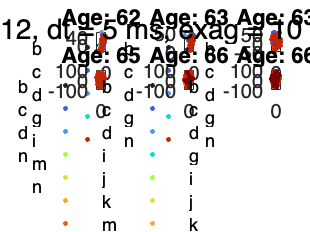

The logical indices in position 1 contain a true value outside of the array bounds.

% Identify unique ages and syllables
uniqueAges = unique(allDays);
uniqueNeuronIDs = unique(allNeurons);
strNeuronID = string(uniqueNeuronIDs); [~,idx] = sort(strNeuronID); 
uniqueNeurons = uniqueNeuronIDs(idx);
uniqueSyls = string(unique(allSyls)); % Convert to string to ensure consistent key type

% Create a fixed colormap for each syllable
clrs = turbo(length(uniqueSyls)); % Use 'lines' or another colormap with enough colors
sylColorMap = containers.Map(uniqueSyls, num2cell(clrs, 2)); % Map syllables to colors

% Number of subplots per row
subplotsPerRow = 3;
numAges = length(uniqueAges);
numNeurons = length(uniqueNeurons);
numRows = ceil(numNeurons / subplotsPerRow); % Calculate the number of rows needed

% Create a figure
figure;

if numNeurons ==1
    tsneSubset = tsneResults;
    sylSubset = allSyls;
    uniqueSyls = unique(sylSubset);
    currentNeuron = uniqueNeurons;

    % Map syllables to their corresponding colors
    colorMatrix = cell2mat(values(sylColorMap, cellstr(sylSubset))); % Convert syllables to cellstr to match Map keys
    selectColors = cell2mat(values(sylColorMap, cellstr(uniqueSyls)));
    % Plot the tSNE results for the current age
    p = gscatter(tsneSubset(:,1), tsneSubset(:,2), sylSubset, selectColors, 'o', 2,'filled');
    legend(uniqueSyls,Location='westoutside',box='off')
    title([birdname,', ','Age: ', num2str(currentNeuron),'+']);
    subtitle(['dt = ', num2str(dt), ' ms, exag = ', num2str(exg), ' perp = ', num2str(perp)]);


else
    % Add a global title and subtitle
    sgtitle([birdname, ', dt = ', num2str(dt*1000), ' ms, exag = ', num2str(exg), ' perp = ', num2str(perp)], fontsize=14);        

    % Loop through each age or Neuron ID
    for i = 1:numNeurons
        % Get the current age and neuron ID
        % currentAge = uniqueAges(i);
        currentNeuron = uniqueNeurons(i);
    
        % Filter data for the current age
        % ageIndices = allDays == currentAge;
        neuronIndices = allNeurons == currentNeuron; 
        tsneSubset = tsneResults(neuronIndices, :);
        sylSubset = allSyls(neuronIndices);
        uniqueSyls = unique(sylSubset);
    
        % Map syllables to their corresponding colors
        colorMatrix = cell2mat(values(sylColorMap, cellstr(sylSubset))); % Convert syllables to cellstr to match Map keys
        selectColors = cell2mat(values(sylColorMap, cellstr(uniqueSyls)));
        
        % Create a subplot
        ax(i) = subplot(numRows, subplotsPerRow, i);
        
        % Plot the tSNE results for the current age
        gscatter(tsneSubset(:,1), tsneSubset(:,2), sylSubset, selectColors, 'o', 2,'filled');
        legend(uniqueSyls,Location='westoutside',box='off')
        strNeurID = num2str(currentNeuron);
        title(['Age: ', strNeurID(1:2)]);
        
    end
    linkaxes(ax)
end


set(gcf,'Visible','On')
% Enable data cursor mode
dcm = datacursormode(gcf);
datacursormode on;
% Set custom callback function
set(dcm, 'UpdateFcn', @(obj, event) customDataTip(obj, event, tsneSubset, sylSubset, allSpikeWords));

## Run UMAP

u = UMAP; % initialize with or without custom params
embedding = u.fit_transform(normSpikeWords); % UMAP results

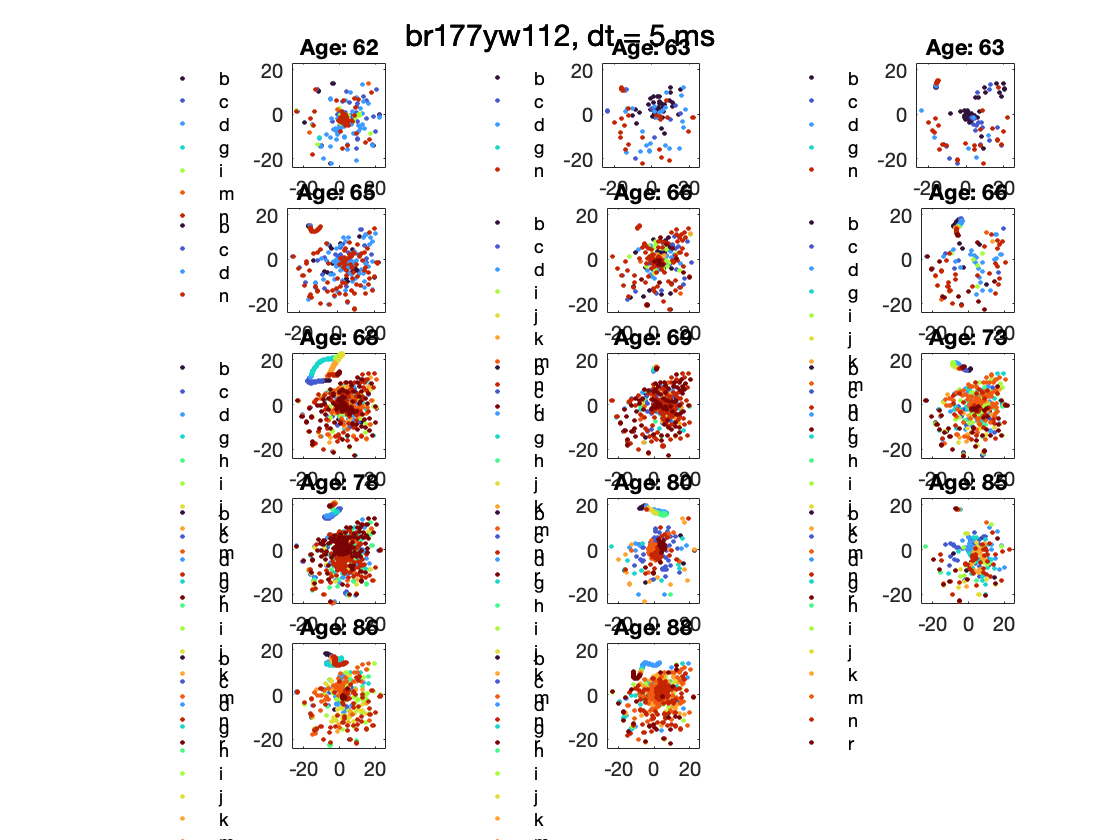

% Identify unique ages and syllables
uniqueAges = unique(allDays);
uniqueNeuronIDs = unique(allNeurons);
strNeuronID = string(uniqueNeuronIDs); [~,idx] = sort(strNeuronID); 
uniqueNeurons = uniqueNeuronIDs(idx);
uniqueSyls = string(unique(allSyls)); % Convert to string to ensure consistent key type

% Create a fixed colormap for each syllable
clrs = turbo(length(uniqueSyls)); % Use 'lines' or another colormap with enough colors
sylColorMap = containers.Map(uniqueSyls, num2cell(clrs, 2)); % Map syllables to colors

% Number of subplots per row
subplotsPerRow = 3;
numAges = length(uniqueAges);
numNeurons = length(uniqueNeurons);
numRows = ceil(numNeurons / subplotsPerRow); % Calculate the number of rows needed

% Create a figure
figure;

if numNeurons ==1
    umapSubset = embedding;
    sylSubset = allSyls;
    uniqueSyls = unique(sylSubset);
    currentNeuron = uniqueNeurons;

    % Map syllables to their corresponding colors
    colorMatrix = cell2mat(values(sylColorMap, cellstr(sylSubset))); % Convert syllables to cellstr to match Map keys
    selectColors = cell2mat(values(sylColorMap, cellstr(uniqueSyls)));
    % Plot the tSNE results for the current age
    gscatter(umapSubset(:,1), umapSubset(:,2), sylSubset, selectColors, 'o', 2,'filled');
    legend(uniqueSyls,Location='westoutside',box='off')
    title([birdname,', ','Age: ', num2str(currentNeuron),'+']);
    subtitle(['dt = ', num2str(dt), ' ms, exag = ', num2str(exg), ' perp = ', num2str(perp)]);
    set(gcf,'Visible','On')
else
    % Add a global title and subtitle
    sgtitle([birdname, ', dt = ', num2str(dt*1000), ' ms']);        

    % Loop through each age or Neuron ID
    for i = 1:numNeurons
        % Get the current age and neuron ID
        % currentAge = uniqueAges(i);
        currentNeuron = uniqueNeurons(i);
    
        % Filter data for the current age
        % ageIndices = allDays == currentAge;
        neuronIndices = allNeurons == currentNeuron; 
        umapSubset = embedding(neuronIndices, :);
        sylSubset = allSyls(neuronIndices);
        uniqueSyls = unique(sylSubset);
    
        % Map syllables to their corresponding colors
        colorMatrix = cell2mat(values(sylColorMap, cellstr(sylSubset))); % Convert syllables to cellstr to match Map keys
        selectColors = cell2mat(values(sylColorMap, cellstr(uniqueSyls)));
        
        % Create a subplot
        ax(i) = subplot(numRows, subplotsPerRow, i);
        
        % Plot the tSNE results for the current age
        gscatter(umapSubset(:,1), umapSubset(:,2), sylSubset, selectColors, 'o', 2,'filled');
        legend(uniqueSyls,Location='westoutside',box='off')
        strNeurID = num2str(currentNeuron);
        title(['Age: ', strNeurID(1:2)]);
    end
    
    linkaxes(ax)
    % subtitle(['dt = ', num2str(dt), ' ms, exag = ', num2str(exg), ' perp = ', num2str(perp)]);
    set(gcf,'Visible','On')
    % subtitle(['Premotor window duration = ', num2str(premotor_duration)]);

end
% Enable data cursor mode
dcm = datacursormode(gcf);
set(dcm, 'DisplayStyle', 'datatip', 'Enable', 'on');

cursordata = getCursorInfo(dcm);
% set(dcm, 'UpdateFcn', @customDataCursor);
% set(dcm, 'UpdateFcn', @(obj, event) displaySpikeWords(event, allSpikeWords));
% set(dcm, 'UpdateFcn', @myupdatefcn);



function txt = customDataTip(~, event_obj, tsneSubset, sylSubset, allSpikeWords)
    % Get clicked point
    pos = event_obj.Position;
    
    % Find global index in tsneSubset
    idx = find(tsneSubset(:,1) == pos(1) & tsneSubset(:,2) == pos(2), 1);

    % Display the corresponding allSpikeWords vector
    if ~isempty(idx)
        spikeWords = allSpikeWords(idx,:); % Extract 8-number vector
        txt = {sprintf('Index: %d', idx), ...
               sprintf('Syllable: %s', sylSubset(idx)), ...
               sprintf('Spikes: [%s]', num2str(spikeWords, '%d '))};
    else
        txt = {'No match found'};
    end
end

